# Class12-Fourier Spectra

close all
clear all

## load the data

atl=xlsread('ATL_MonMeanTemp_1879_2020.xls');
x = atl(1:128,1);
y = atl(1:128,7); % June temp

## apply FFT

N=length(y);
c = fft(y);
freq = [0:1/N:1/2 -1/2+1/N:1/N:(-1/N)];
%disp(num2str(c,2))

## visualize the variance contained within each frequency

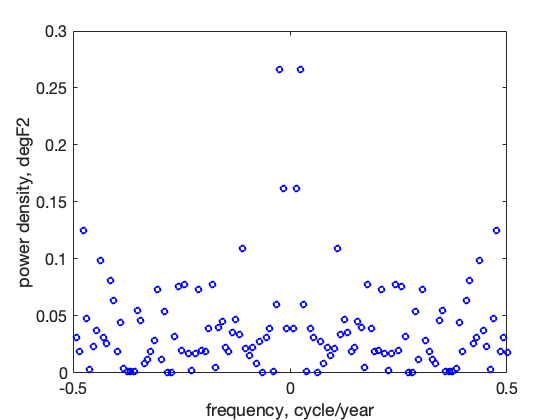

figure(1);
var0=c(2:N).*conj(c(2:N))/N/(N-1);
plot(freq(2:N),real(var0),'bo','linewidth',2);
xlabel('frequency, cycle/year')
ylabel('power density, degF2');
set(gca,'fontsize',16);

## practically, we just need to consider positive/negative frequencies

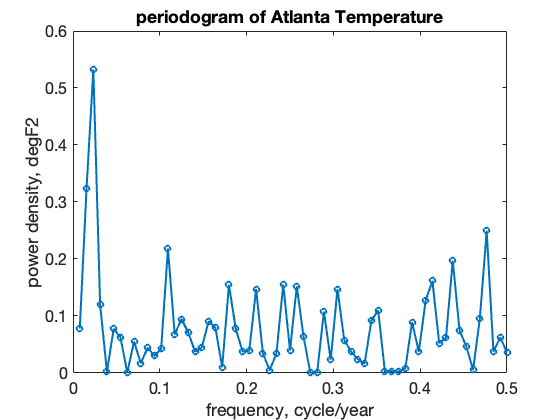

figure(2);
var0=2*c(2:round(N/2)+1).*conj(c(2:round(N/2)+1))/N/(N-1);
freq1=[1/N:1/N:1/2];
plot(freq1,real(var0),'o-','linewidth',2);
xlabel('frequency, cycle/year')
ylabel('power density, degF2');
title('periodogram of Atlanta Temperature');
set(gca,'fontsize',16);

## Application 1: data compression, approximation with reduced dimensions

%let's pick up only strong frequency components : X% compression factor
%Truncation: In the frequency domain, I look at X percentile value of Fourier coefficient, and only retain stronger coefficients by setting weaker ones to zero.¶
X=75;
c2=c.*conj(c)/N/(N-1);
indexX=prctile(c2,X);
cX=c;
cX(real(c2)<indexX)=0; % remove all weak frequency components

## plot the periodogram of filtered data

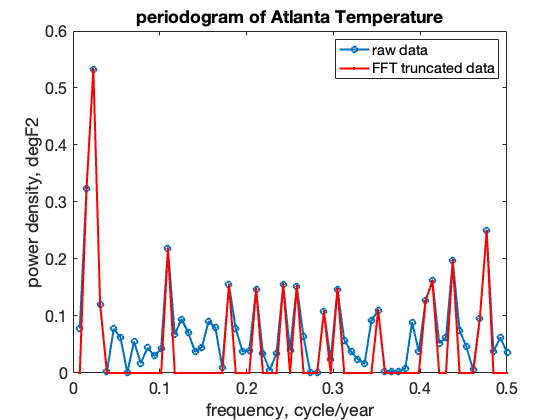

figure(2);
hold on;
var1=2*cX(2:round(N/2)+1).*conj(cX(2:round(N/2)+1))/N/(N-1);
plot(freq1,real(var1),'r.-','linewidth',2);
hold off;
legend({'raw data' 'FFT truncated data'});

## inverse fft to reconstrct in time domain

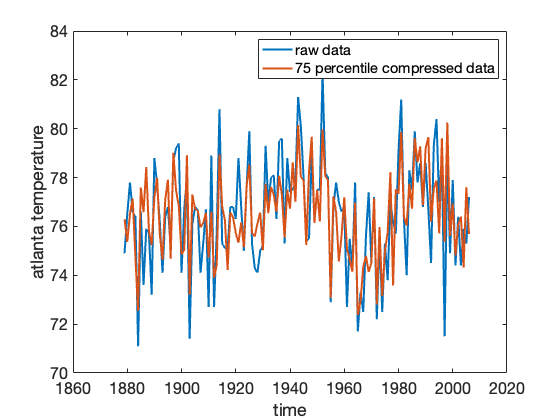

figure(3);
yest=ifft(cX); 
p(1)=plot(x,y,'linewidth',2);
hold on;
p(2)=plot(x,real(yest),'linewidth',2);
hold off;
xlabel('time')
ylabel('atlanta temperature')
legend(p,{'raw data' [num2str(X),' percentile compressed data']})
set(gca,'fontsize',16);

## check how much variance is retained in the X percentile Fourier coefficients

% In physical space 
y_var=var(y);
yest_var=var(real(yest));
disp(['Truncated data retained ', ... 
    num2str(yest_var/y_var*100,2),' percent of variance']);

Truncated data retained 60 percent of variance


% In frequency space
disp(['Truncated data retained ', ... 
    num2str(sum(var1)/sum(var0)*100,2),' percent of variance']);

Truncated data retained 60 percent of variance


#### Check the correlation as well

% correlation coefficient
Rval=corrcoef(y,real(yest));
disp(['The correlation is ',num2str(Rval(1,2),2)])

The correlation is 0.78


## Application 2: FFT frequency filter

## Let's say we are only interested in 10+ year frequency for climate studies

## We truncate the Fourier coefficient of higher frequency than 1/10 years.

Period=10;
cutoff_freq=1/Period;
cflt=c;
cflt(abs(freq)>cutoff_freq)=0;

## plot the periodogram of filtered data

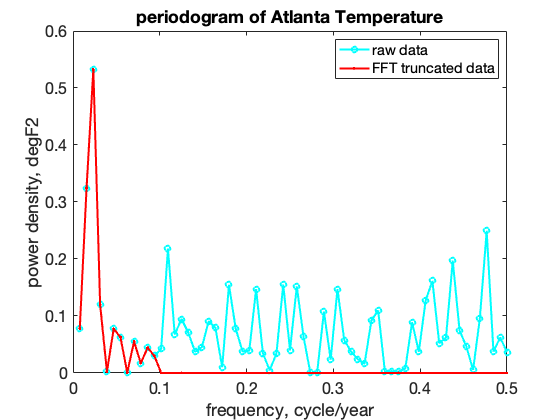

figure(4);
var1=2*cflt(2:round(N/2)+1).*conj(cflt(2:round(N/2)+1))/N/(N-1);
plot(freq1,real(var0),'co-','linewidth',2);
hold on;
plot(freq1,real(var1),'r.-','linewidth',2);
hold off;
legend({'raw data' 'FFT truncated data'});
xlabel('frequency, cycle/year')
ylabel('power density, degF2');
title('periodogram of Atlanta Temperature');
set(gca,'fontsize',16);

## inverse fft to reconstrct in time domain

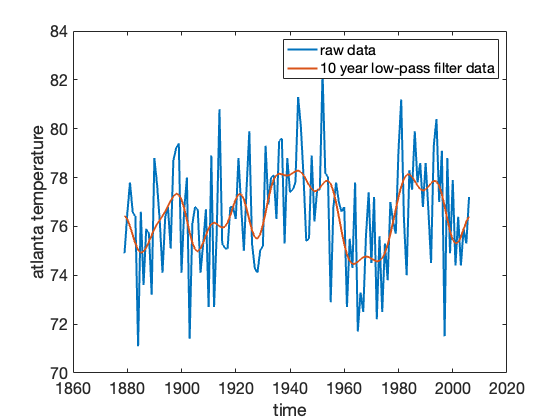

figure(5);
yest=ifft(cflt); 
p(1)=plot(x,y,'linewidth',2);
hold on;
p(2)=plot(x,real(yest),'linewidth',2);
hold off;
xlabel('time')
ylabel('atlanta temperature')
legend(p,{'raw data' [num2str(Period),' year low-pass filter data']})
set(gca,'fontsize',16);

## Check how much variance is retained in the low-pass filtered time series

% In physical space 
y_var=var(y);
yest_var=var(real(yest));
disp([num2str(Period),' year low-pass filter data retained ', ... 
    num2str(yest_var/y_var*100,2),' percent of variance']);

10 year low-pass filter data retained 27 percent of variance


% In frequency space
disp([num2str(Period),' year low-pass filter data retained ', ... 
    num2str(sum(var1)/sum(var0)*100,2),' percent of variance']);

10 year low-pass filter data retained 27 percent of variance


#### Check the correlation as well

% correlation coefficient
Rval=corrcoef(y,real(yest));
disp(['The correlation is ',num2str(Rval(1,2),2)])

The correlation is 0.52
